# Modeling LGN

Using LSY's email and CHSL 2022

Goal: Use the equations to generate LGN input patterns, then fix in precomputations.

## 1. Calibration of LGN dynamics

I(t) = I_B = 0.1/ms, \tau_leak = 0.1/ms

N(t) = sum of Poisson timed kicks with rate 1/ms and size 0.075

When V reaches a threshold V_th, the cell fires, V is reset to 0 and the dynamics resumes.

Exact value of V_th (\approx 1) is chosen to give ~20 spikes/s.

Time step of simulation : 0.1 ms; Once V_th is found it will be fixed.

fGoal = 20; % Goal of BG LGN Frs: 20 Hz = 20 times/s

dt = 0.1; T = 1000 * 1e3;
I_B = 0.100; tau_L = 0.1; % ALL Units in MS!!
% \tau_leak = 0.1/ms = 1/10 ms, the time scale is faster than Leak of L4
% neurons
lambdaN = 0.1; fN = 0.075;

V_thre = 1.002; % this needs testing!
V_res = 0;

TGrid = 0:dt:T;
pPoiss = lambdaN * dt;
NSeq = double(rand(1,length(TGrid)) < pPoiss) .* ...
    (double(rand(1,length(TGrid)) <= 1/2)*2 - 1);

% at most this many spikes, unlikely for more
SpTime = zeros(2*fGoal * floor(T/1e3), 1);

Start simulation for BG LGN

V_LGN = zeros(size(TGrid)); % start from 0 then simulate
TInd = 1;
SpInd = 1;
tic
while TInd < length(TGrid)
    V_LGN(TInd+1) = V_LGN(TInd) + ...
        dt * (I_B - tau_L*(V_LGN(TInd) - V_res)) + ...
        NSeq(TInd) * fN;
    % Once firing: cross, reset, and record the timing
    if V_LGN(TInd+1) >= V_thre
        V_LGN(TInd+1) = V_res;
        SpTime(SpInd) = TGrid(TInd);
        SpInd = SpInd + 1;
    end
    TInd = TInd + 1;
end
toc

Elapsed time is 0.117153 seconds.



FLGN_bg = length(find(SpTime)) / floor(T/1e3);

## 2. visual inputs: drifting gratings

## LGN Kernels

close all

C = 1; % contrast
phi = 0; % initial phase
L0 = 1.0; % or 100? light internsity
Q0 = 0.5; % constant for visual gain; L0*Q0 can be combined.

spatial freq

g_abs = 2.5; % c/d, spatial frequency
theta = 0; % 0-pi
g = [cos(theta);sin(theta)];
g = g/norm(g) * g_abs;

now define receptive field

x_int = -1:0.005:1; y_int = -1:0.005:1;
[x1,x2] = meshgrid(x_int,y_int); % the whole field: 2 deg
sigma_a = 0.0894; sigma_b = 0.1259;
a = 1; b = 0.74; % parameters for the mexican hat
A = @(x,y,x0,y0) ... % x and y are are scalars or 2D meshgrids;
    ...% x0 and y0 are scalars:  the center of the kernel
    ( a/sigma_a^2 * exp(-((x-x0).^2 + (y-y0).^2)/sigma_a^2) - ...
      b/sigma_b^2 * exp(-((x-x0).^2 + (y-y0).^2)/sigma_b^2) )/pi;
Ax = A(x1,x2,0,0);

LGN temporal kernel

tau0 = 3.66; tau1 = 7.16; % all in ms
Koff = @(t) ... % t in ms
    t.^6/tau0^7 .* exp( - t/tau0) - ...
    t.^6/tau1^7 .* exp( - t/tau1);

fAll = 2:2:24; % Hz, cycles/second, temporal freqeuency;
FLGN_on_All = zeros(size(fAll));

fig1 = figure(1);
PlotId = [1:3:22, 2:3:23, 3:3:24];
for fId = 1:length(fAll) 
    f = fAll(fId)/1e3; %  normalized for ms

   Grating: spatiotemporal

    L = @(x,y,t) ... % x and y as above; t in second
        (C * sin(-2*pi*(g(1)*x + g(2)*y) + 2*pi*f*t + phi) + 1) * L0;
    Lxyt = L(x1,x2,0);

Plot figs to make sure everything is ok

%     TK = 0:0.1:100;
%     
%     figure
%     subplot(2,3,1)
%     plot(TK,Koff(TK));
%     xlabel('t (ms)'); ylabel('K^{off}')
%     title('K(t): LGN off temporal kernel')
%     
%     subplot(2,3,[2,3])
%     plot(x_int,Ax(floor(end/2),:))
%     %mesh(x1,x2,Ax)
%     %imagesc(-1:0.005:1,-1:0.005:1,Ax)
%     %set(gca,'YDir','Normal');
%     %colormap jet; colorbar
%     %axis([-0.5 0.5 -0.5 0.5])
%     xlabel('x (deg)'); ylabel('A(x)')
%     %axis square
%     xlim([-0.3 0.3]);%ylim([-0.3 0.3]);
%     title('A(x): LGN off spatial kernel')
%     grid on
% 
%     
%     tL = [0 25 50];
%     for ii = 1:length(tL)
%         subplot(2,length(tL),ii + 3)
%         imagesc(-1:0.005:1,-1:0.005:1,L(x1,x2,tL(ii)))
%         set(gca,'YDir','Normal'); colormap jet; colorbar
%         axis([-0.5 0.5 -0.5 0.5])
%         xlabel('x (deg)'); ylabel('y (deg)'); title(sprintf('%d ms',tL(ii)))
%         axis square
%     end

    %close all

### 2.1 Do integration for inputs

Q_Inter = @(x,y,s,t) Koff(s) * A(-x,-y,0,0) .* L(x,y,t-s);

Need to first precompute for all t, then quote from series;

    Tlength = 5; % 5s
    T_AL = 0:dt:1e3; %  time grid for 1s
    AL_allT = zeros(size(T_AL));

    x_int = -0.5:0.005:0.5; y_int = -0.5:0.005:0.5;

    [x1,x2] = meshgrid(x_int,y_int); % the whole field: 2 deg
    for ALId = 1:length(T_AL)
        AL_allT(ALId) = ...
            sum(A(-x1,-x2,0,0) .* L(x1,x2,T_AL(ALId)),'all') * ...
            (x_int(2)-x_int(1)) * (y_int(2)-y_int(1));
    end
    AL_allT = [repmat(AL_allT(1:end-1),1,Tlength),AL_allT(end)];

    Tlgn = 0:dt:5*1e3; % in ms
    TIdTrunc = floor(200/dt); % temporal window at most this large
    Koff_Int = Koff(Tlgn);
    Qt_All = zeros(size(Tlgn)); % Qt in every time bin
    for TId = 1:length(Tlgn)
        WinSize = min(TIdTrunc,TId);
        Qt_All(TId) = ...
            sum(Koff_Int(1:WinSize) .* AL_allT(TId:-1:TId-WinSize+1),'all') * dt;
    end

plot Qt

    % plot(Tlgn,Qt_All)
    % xlim([1e3 2e3])
    % xlabel('t (ms)'); title('Q(t)');

on and off I

    Qt_Use = Qt_All/1e3 * Q0; % modified by Q0;

    I_on  = I_B + Qt_Use; I_on(I_on<0) = 0;
    I_off = I_B - Qt_Use; I_off(I_off<0) = 0;

2.2 driven LGN cell:

    I_drive = I_on(floor(1e3/dt):end);

    f_drive_Goal = 100;
    T_drive = 4e3;
    TGrid = 0:dt:T_drive;
    pPoiss = lambdaN * dt;
    NSeq = double(rand(1,length(TGrid)) < pPoiss) .* ...
        (double(rand(1,length(TGrid)) <= 1/2)*2 - 1);

    % at most this many spikes, unlikely for more
    SpTime = zeros(2*f_drive_Goal * floor(T_drive/1e3), 1);

Start simulation for BG LGN

    V_LGN = zeros(size(TGrid)); % start from 0 then simulate
    TInd = 1;
    SpInd = 1;
    tic
    while TInd < length(TGrid)
        V_LGN(TInd+1) = V_LGN(TInd) + ...
            dt * (I_drive(TInd) - tau_L*(V_LGN(TInd) - V_res)) + ...
            NSeq(TInd) * fN;
        % Once firing: cross, reset, and record the timing
        if V_LGN(TInd+1) >= V_thre
            V_LGN(TInd+1) = V_res;
            SpTime(SpInd) = TGrid(TInd);
            SpInd = SpInd + 1;
        end
        TInd = TInd + 1;
    end
    toc

    FLGN_on_All(fId) = length(find(SpTime)) / floor(T_drive/1e3);

plot firing events and V

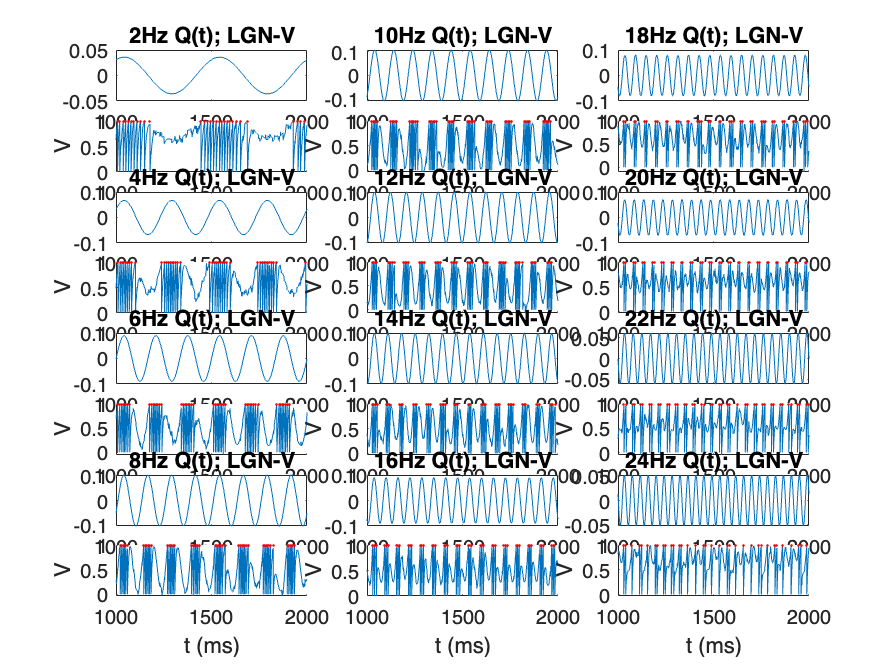

Elapsed time is 0.002543 seconds.
Elapsed time is 0.000909 seconds.
Elapsed time is 0.000410 seconds.
Elapsed time is 0.000557 seconds.
Elapsed time is 0.000795 seconds.
Elapsed time is 0.000438 seconds.
Elapsed time is 0.000382 seconds.
Elapsed time is 0.000386 seconds.
Elapsed time is 0.000384 seconds.
Elapsed time is 0.000383 seconds.
Elapsed time is 0.000410 seconds.
Elapsed time is 0.000390 seconds.


    subplot(8,3,PlotId(2*(fId-1)+1))
    plot(Tlgn,Qt_Use)
    xlim([1e3 2e3])
    title(sprintf('%dHz Q(t); LGN-V',fAll(fId)));
    
    subplot(8,3,PlotId(2*fId))
    hold on
    plot(TGrid,V_LGN);
    scatter(SpTime, ones(size(SpTime)),15,'r.')
    xlim([1e3 2e3])
    xlabel('t (ms)'); ylabel('V'); 
end

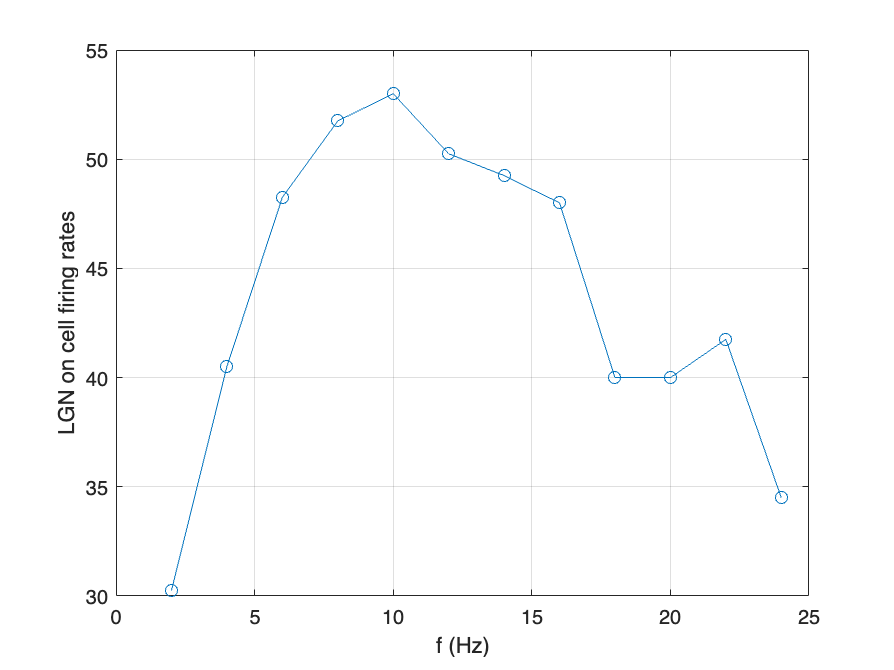


figure(2)
plot(fAll,FLGN_on_All,'o-')
xlabel('f (Hz)'); ylabel('LGN on cell firing rates')
grid on